Ok, so, filtering out a baseline signal this way doesn't work at all. This is because the dominant freqencies quickly become the ones at the points of repeat of the baseline signal.

% baseline filtering
clear;
load 'houseprint';

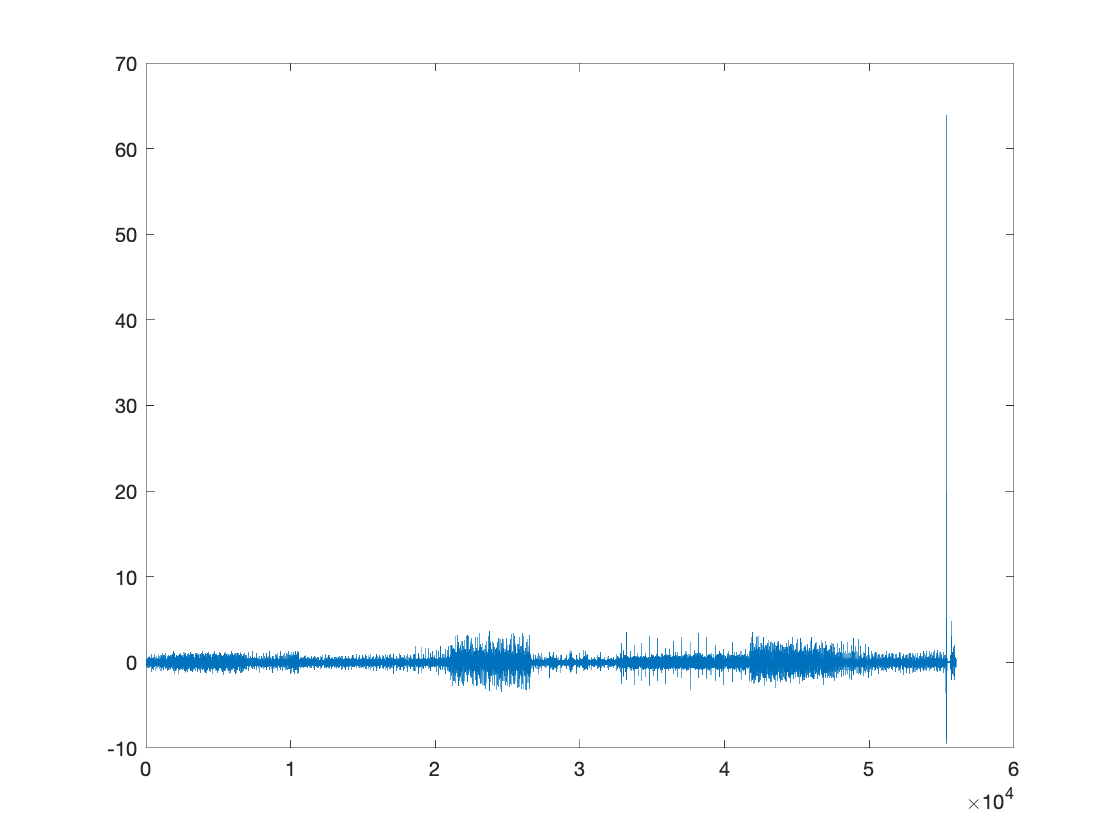

figure()
a = timetable2table(Acceleration);
accelData = [a.X a.Y a.Z]';
x = vecnorm(accelData);
x = x - mean(x);
plot(x)

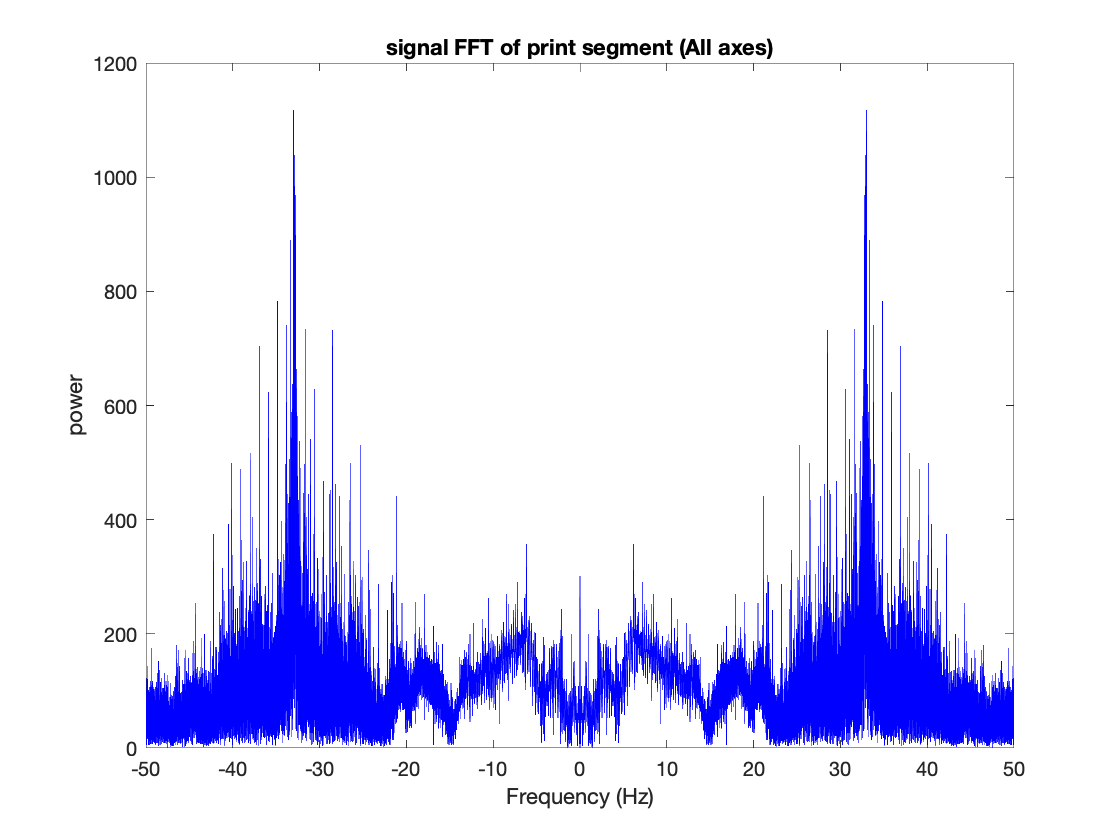

% x = accelData(:,1);
N = length(x);
Fs = 100;
f = linspace(-Fs/2, Fs/2 - Fs/N, N) + Fs/(2*N)*mod(N, 2);
FA = fft(x);
fftOutput = fftshift(abs(FA));
plot(f,fftOutput,'b');
title("signal FFT of print segment (All axes)")
xlabel("Frequency (Hz)")
ylabel("power")

data = load('data/baseline.mat');
a_base = timetable2table(data.Acceleration);
accelData_base = [a_base.X a_base.Y a_base.Z]';
multiplier = 56007 / 1946

multiplier = 28.7806

lemthy_data = repmat(accelData_base', round(multiplier)+1,1)

lemthy_data =     0.3485    0.0867    8.9170
    0.5086   -0.0849    9.7205
    0.4024    0.0930    9.9992
    0.3212    0.1192    9.7751
    0.4036    0.0220   10.0531
    0.3591    0.0698    9.7967
    0.1947    0.1242    9.6840
    0.4597   -0.0256   10.0420
    0.4625    0.1218    9.4826
    0.3546    0.0079    9.5208


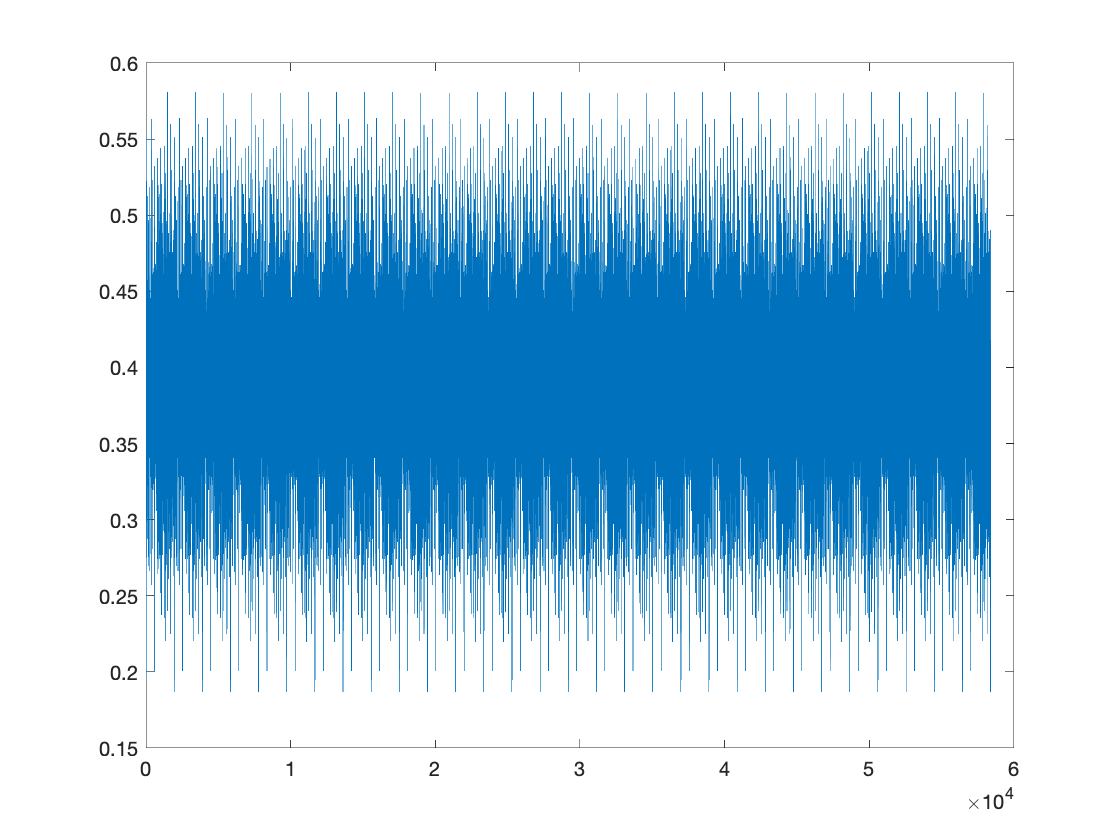

plot(lemthy_data(:,1)) % plot one axis

sample_size = size(accelData,2)

sample_size = 56007

x_base = vecnorm(lemthy_data(1:sample_size,:)');

FA_base = fft(x_base);

FA_output = FA - FA_base;

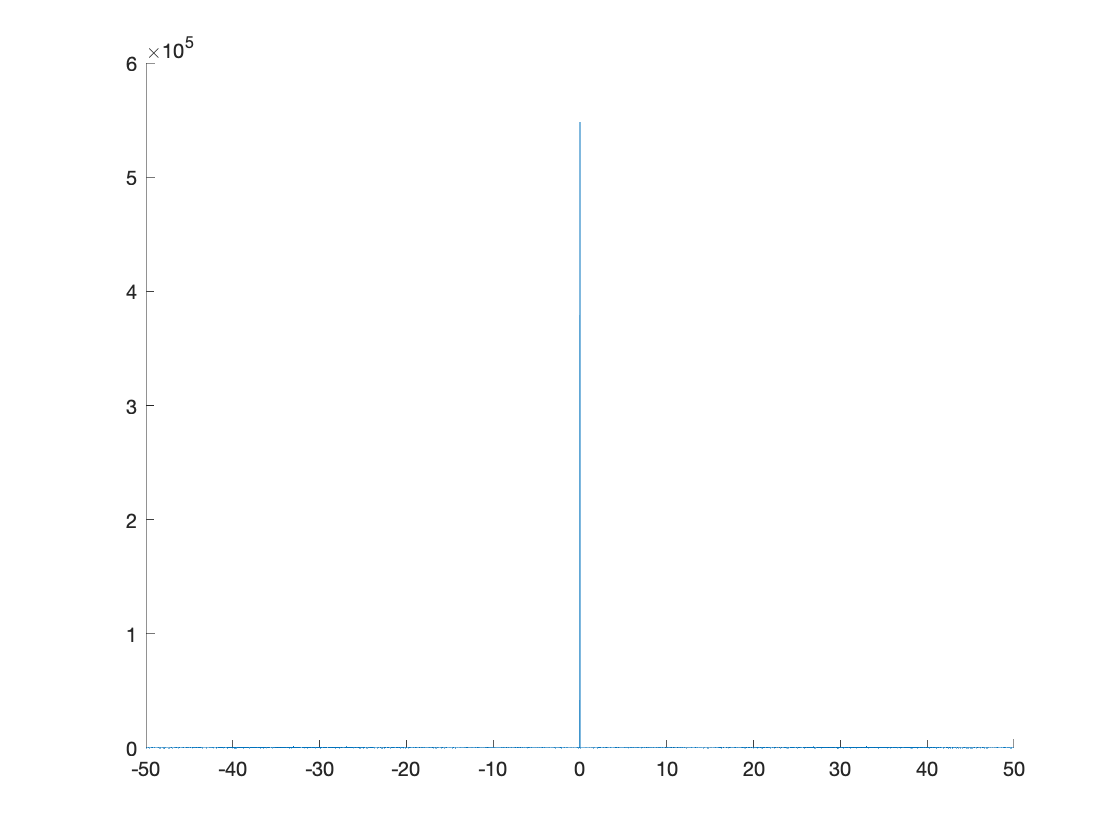

figure()
% plot(f,fftshift(abs(FA)),'b');
hold on
plot(f,fftshift(abs(FA_output)));

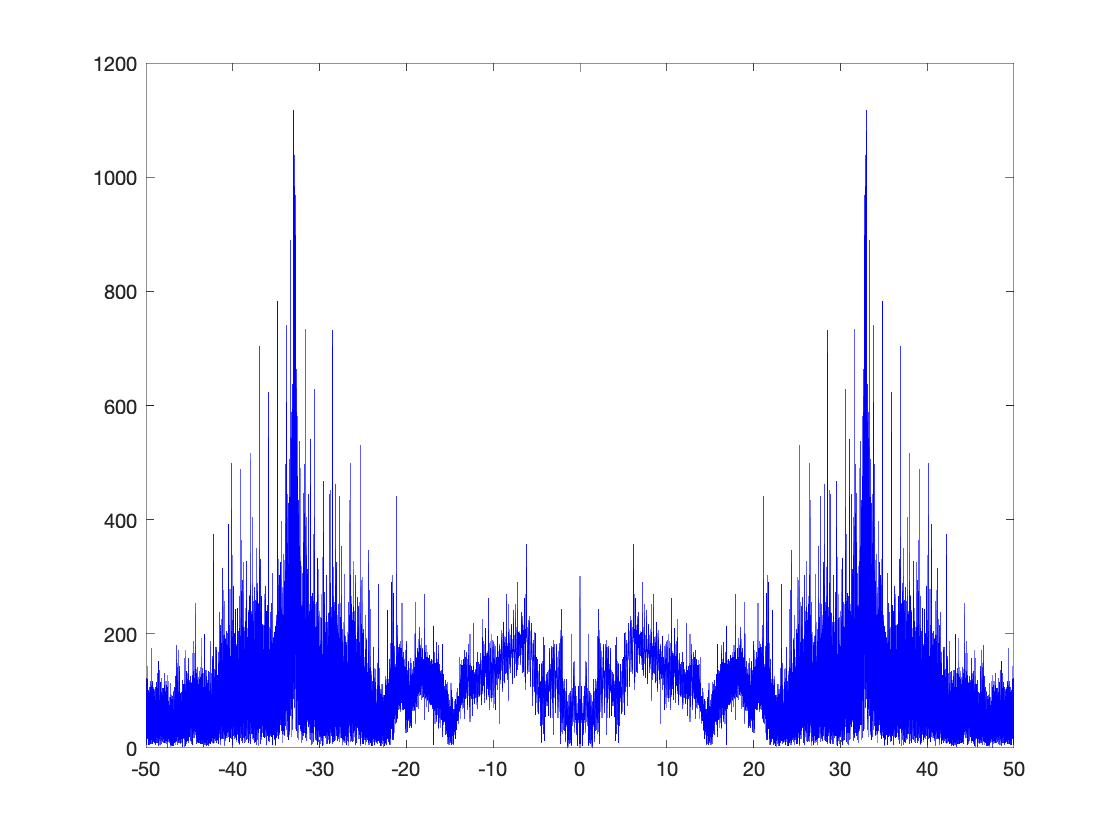

figure()
plot(f,fftshift(abs(FA)),'b');